clear all
close all
clc


%% logfile from REGBOT:
%  1    time 0.000 sec, from Naja (39)
%  2  3  4  5   (mission 0), state 2, entered (thread 1, line 0), events 0x0 (bit-flags)
%  6  7 Motor velocity ref left, right: 0.0000 0.0000
%  8  9 Motor voltage [V] left, right: 0.00 0.00
% 10 13 Wheel velocity [m/s] left, right: 0.0000 0.0000 delay 0.0000 0.0000 (sec)
% 14 15 16 17 Pose x,y,h,tilt [m,m,rad,rad]: 0 0 0 -0.655069
% 18    Battery voltage [V]
data1 = readtable('data/data_upside_down_1.txt',CommentStyle="%");
%data2 = readtable('data/data_wheel_down_1.txt',CommentStyle="%");

data1 = fillmissing(data1,'nearest');
%data2 = fillmissing(data2,'nearest');




t = table2array(data1(:,1));     % time stamps
u_L = table2array(data1(:,8));   % left motor voltage
u_R = table2array(data1(:,9));   % right motor voltage
v_L = table2array(data1(:,10));  % left motor velocity 
v_R = table2array(data1(:,11));  % right motor velocity
T_s = t(2) - t(1);              % compute sampling time

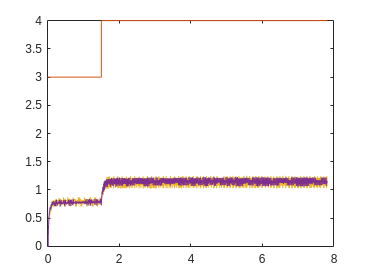

% Create a figure with subplots
figure;
plot(t,u_L)
hold on
plot(t,u_R)
hold on
plot(t,v_L)
hold on
plot(t,v_R)

data2 = readtable('data/data_wheel_down_1.txt',CommentStyle="%");
data2 = fillmissing(data2,'nearest');

t = table2array(data2(:,1));     % time stamps
u_L = table2array(data2(:,8));   % left motor voltage
u_R = table2array(data2(:,9));   % right motor voltage
v_L = table2array(data2(:,10));  % left motor velocity 
v_R = table2array(data2(:,11));  % right motor velocity
T_s = t(2) - t(1);              % compute sampling time

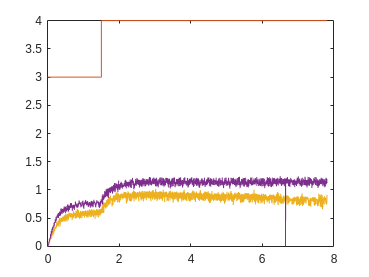

 % Create a figure with subplots
figure;
plot(t,u_L)
hold on
plot(t,u_R)
hold on
plot(t,v_L)
hold on
plot(t,v_R)